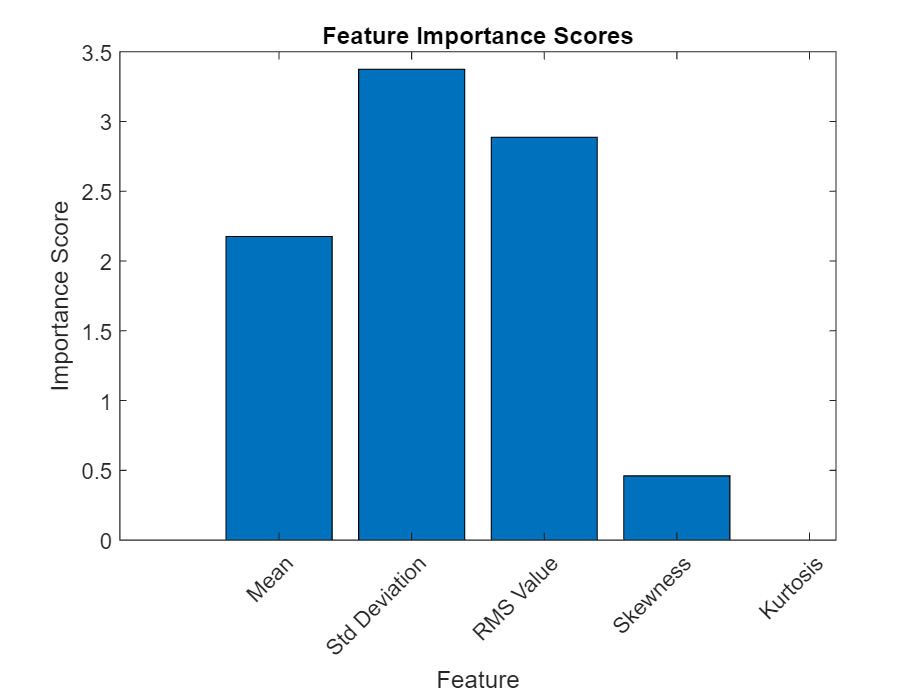


clc;
clear;
addpath(genpath('SOM-Toolbox'));

% Load training data and labels
train_data_x = load('data_train.mat');
train_data_y = load('data_train_labels.mat');

% Extracting the actual data from the loaded variables
train_data_x = train_data_x.data_train;
train_data_y = train_data_y.data_train_labels;

% Define label names
label_names = {'normal', 'roller', 'inner', 'outer', ...
               'inner+roller', 'outer+inner', 'outer+inner+roller', 'outer+roller'};

% Use 'data_train_labels' as your target labels
target_labels = train_data_y';

% Preallocate feature matrix
num_columns = numel(train_data_x);
num_features = 4; % Including mean, std, rms, skewness, kurtosis, 1st harmonic, 2nd harmonic, crest factor, impulse factor, and clearance factor
time_domain_features = zeros(num_columns, num_features);

theta = 14.94 * pi / 180;

% Compute and populate the time domain feature matrix
for col = 1:num_columns
    data = train_data_x{col};
    mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    mav_value = mean(abs(data));
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    first_order_harmonic = fft_normalized(2);
    second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    impulse_factor = max(data) / mean(abs(data));
    clearance_factor = max(data) / (max(data) - min(data));
    p2p=max(data)-min(data);
    bin_indices = (0:N-1)';
    spectral_centroid_bin = sum(bin_indices .* fft_normalized) / sum(fft_normalized);
    shape_factor = rms_value / mav_value;
    zero_crossings = sum(abs(diff(data > 0))) / length(data);
    waveform_length = sum(abs(diff(data)));
    slope_changes = diff(data);
    ssc_count = sum((slope_changes(1:end-1) .* slope_changes(2:end)) < -theta);
    time_domain_features(col, :) = [skewness_value, std_deviation,mav_value,first_order_harmonic];
end

% Convert numeric target_labels to cell array of strings using label_names
target_labels_cell = cell(size(target_labels));
for i = 1:numel(target_labels)
    target_labels_cell{i} = label_names{target_labels(i)};
end
target_labels_numeric = grp2idx(target_labels_cell); % Convert to numeric if they are cell strings

% Train a Random Forest model
nTrees = 100; % Example: 100 trees
rfModel = TreeBagger(nTrees, time_domain_features, target_labels_numeric, 'Method', 'classification', 'OOBVarImp', 'On');

% Extract feature importance
featureImportance = rfModel.OOBPermutedVarDeltaError;

% Define your feature names
feature_names = {'Mean', 'Std Deviation', 'RMS Value', 'Skewness', 'Kurtosis', ...
                 'first_harmonic', 'second_harmonic','Crest Factor', 'Impulse Factor', 'Clearance Factor'};

% Visualize feature importance with specific feature names
figure;
bar(featureImportance);
title('Feature Importance Scores');
xlabel('Feature');
ylabel('Importance Score');
xticks(1:length(feature_names));
xticklabels(feature_names); % Use your feature names here
xtickangle(45);


% Perform k-fold cross-validation
k = 5; % Number of folds
cv = cvpartition(numel(target_labels), 'KFold', k);

% Display the partitioning of k-fold and the number of data in each fold
disp('Partitioning of K-Fold Cross-Validation:');

Partitioning of K-Fold Cross-Validation:


for i = 1:k
    train_idx = training(cv, i);
    val_idx = test(cv, i);
    disp(['Fold ', num2str(i), ': Training Set - ', num2str(sum(train_idx)), ' samples, Validation Set - ', num2str(sum(val_idx)), ' samples']);
end

Fold 1: Training Set - 1639 samples, Validation Set - 409 samples
Fold 2: Training Set - 1638 samples, Validation Set - 410 samples
Fold 3: Training Set - 1638 samples, Validation Set - 410 samples
Fold 4: Training Set - 1638 samples, Validation Set - 410 samples
Fold 5: Training Set - 1639 samples, Validation Set - 409 samples



% Initialize variables to store evaluation metrics
accuracy = zeros(k, 1);
conf_matrices = cell(k, 1);

for i = 1:k
    % Training set
    train_idx = training(cv, i);
    train_features = time_domain_features(train_idx, :);
    train_labels = target_labels(train_idx);
    
    % Validation set
    val_idx = test(cv, i);
    val_features = time_domain_features(val_idx, :);
    val_labels = target_labels(val_idx);
    
    % Train SOM Model
    sD = som_data_struct(train_features, 'name', 'Machine Condition Data', 'comp_names', {'Skewness','Standard Deviation','MAV','First order harmonic'});
    sD = som_label(sD, 'add', 1:size(train_features, 1), arrayfun(@(x) label_names{x}, train_labels, 'UniformOutput', false));
    sMap = som_make(sD);
    
    % Calculate pairwise distances between all neurons in the SOM for later use
    neuron_distances = pdist2(sMap.codebook, sMap.codebook);
    
    % Automatic labeling of the SOM
    sMap = som_autolabel(sMap, sD, 'vote'); % Using 'vote' method for automatic labeling
    
    % Handle unlabeled neurons
    numNeurons = size(sMap.codebook, 1); % Number of neurons in SOM
    labeledIndices = find(~cellfun(@isempty, sMap.labels)); % Indices of labeled neurons
    unlabeledIndices = find(cellfun(@isempty, sMap.labels)); % Indices of unlabeled neurons
    
    for j = 1:length(unlabeledIndices)
        currentUnlabeled = unlabeledIndices(j);
        
        % Calculate distances from this unlabeled neuron to all labeled neurons
        distancesToLabeled = neuron_distances(currentUnlabeled, labeledIndices);
        
        % Find the nearest labeled neuron
        [~, minIndex] = min(distancesToLabeled);
        nearestLabeledNeuronIndex = labeledIndices(minIndex);
        
        % Assign the label of the nearest labeled neuron to the current unlabeled neuron
        sMap.labels{currentUnlabeled} = sMap.labels{nearestLabeledNeuronIndex};
    end
    
    % Find best-matching units (BMUs) for validation data on the trained SOM
    bmu_indices = som_bmus(sMap, val_features);
    
    predicted_labels = cell(length(bmu_indices), 1);
    for j = 1:length(bmu_indices)
        predicted_labels{j} = sMap.labels{bmu_indices(j),1};
    end
    
    % Convert numeric val_labels to cell array of strings using label_names
    actual_labels_cell = cell(size(val_labels));
    for j = 1:numel(val_labels)
        actual_labels_cell{j} = label_names{val_labels(j)};
    end
    
    % Evaluate performance
    accuracy_som(i) = sum(strcmp(predicted_labels, actual_labels_cell)) / numel(val_labels);
    conf_matrices_som{i} = confusionmat(actual_labels_cell, predicted_labels, 'Order', label_names);
    for j = 1:numel(label_names)
        TP = conf_matrices_som{i}(j, j);
        FP = sum(conf_matrices_som{i}(:, j)) - TP;
        FN = sum(conf_matrices_som{i}(j, :)) - TP;
        TN = sum(conf_matrices_som{i}(:)) - TP - FP - FN;
        precision_som(i, j) = TP / (TP + FP);
        recall_som(i, j) = TP / (TP + FN);
        f1Scores_som(i, j) = 2 * ((precision_som(i, j) * recall_som(i, j)) / (precision_som(i, j) + recall_som(i, j)));
    end
end

Determining map size...
 map size [35, 6]
Initialization...
Training using batch algorithm...
Rough training phase...
Training:   0/   0 s
Finetuning phase...
Training:   0/   0 s
Final quantization error: 1.293
Final topographic error:  0.113
Final combined error:  3.062
Determining map size...
 map size [35, 6]
Initialization...
Training using batch algorithm...
Rough training phase...
Training:   0/   0 s
Finetuning phase...
Training:   0/   0 s
Final quantization error: 1.238
Final topographic error:  0.107
Final combined error:  2.908
Determining map size...
 map size [35, 6]
Initialization...
Training using batch algorithm...
Rough training phase...
Training:   0/   0 s
Finetuning phase...
Training:   0/   0 s
Final quantization error: 1.316
Final topographic error:  0.089
Final combined error:  3.049
Determining map size...
 map size [35, 6]
Initialization...
Training using batch algorithm...
Rough training phase...
Training:   0/   0 s
Finetuning phase...
Training:   0/   0 s
F



% Calculate average performance metrics for Support Vector Machine (SVM)
avg_accuracy_som = mean(accuracy_som);
avg_precision_som = mean(precision_som, 1);
avg_recall_som = mean(recall_som, 1);
avg_f1Scores_som = mean(f1Scores_som, 1);

% Display k-fold cross-validation results for Self-Organizing Maps(SOM)
disp("Support Vector Machine (SVM) Results:");

Support Vector Machine (SVM) Results:


disp(['Average Accuracy: ', num2str(avg_accuracy_som * 100), '%']);

Average Accuracy: 99.3166%


disp('Average Precision:');

Average Precision:


disp(avg_precision_som);

    1.0000    0.9960    0.9967    1.0000    0.9718    0.9854    1.0000    0.9964



disp('Average Recall:');

Average Recall:


disp(avg_recall_som);

    0.9953    1.0000    0.9961    1.0000    0.9850    0.9725    1.0000    0.9964



disp('Average F1-Score:');

Average F1-Score:


disp(avg_f1Scores_som);

    0.9976    0.9980    0.9964    1.0000    0.9782    0.9788    1.0000    0.9963




% Display k-fold cross-validation results for SOM
disp('For SOM:');

For SOM:


disp(['Average Accuracy: ', num2str(avg_accuracy_som * 100), '%']);

Average Accuracy: 99.3166%


disp('Confusion Matrices:');

Confusion Matrices:


Fold 1


    50     0     0     0     0     0     0     0
     0    53     0     0     0     0     0     0
     0     0    60     0     0     0     0     0
     0     0     0    51     0     0     0     0
     0     0     0     0    39     0     0     0
     0     0     0     0     2    42     0     0
     0     0     0     0     0     0    57     0
     0     0     1     0     0     0     0    54



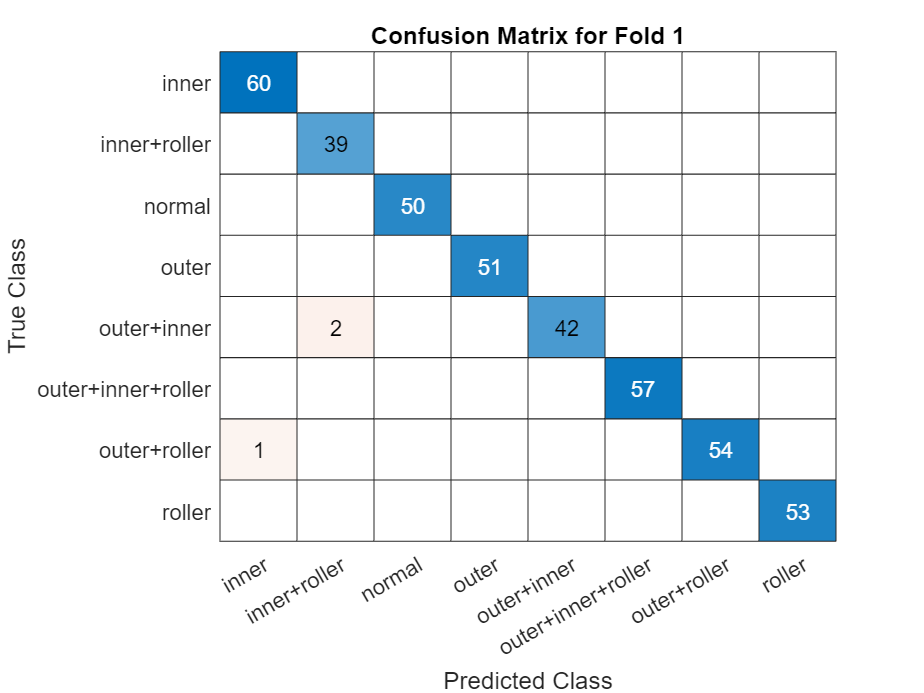

Fold 2


    42     1     0     0     0     0     0     0
     0    49     0     0     0     0     0     0
     0     0    41     0     0     0     0     0
     0     0     0    55     0     0     0     0
     0     0     0     0    52     0     0     0
     0     0     0     0     1    58     0     0
     0     0     0     0     0     0    59     0
     0     0     0     0     0     0     0    52



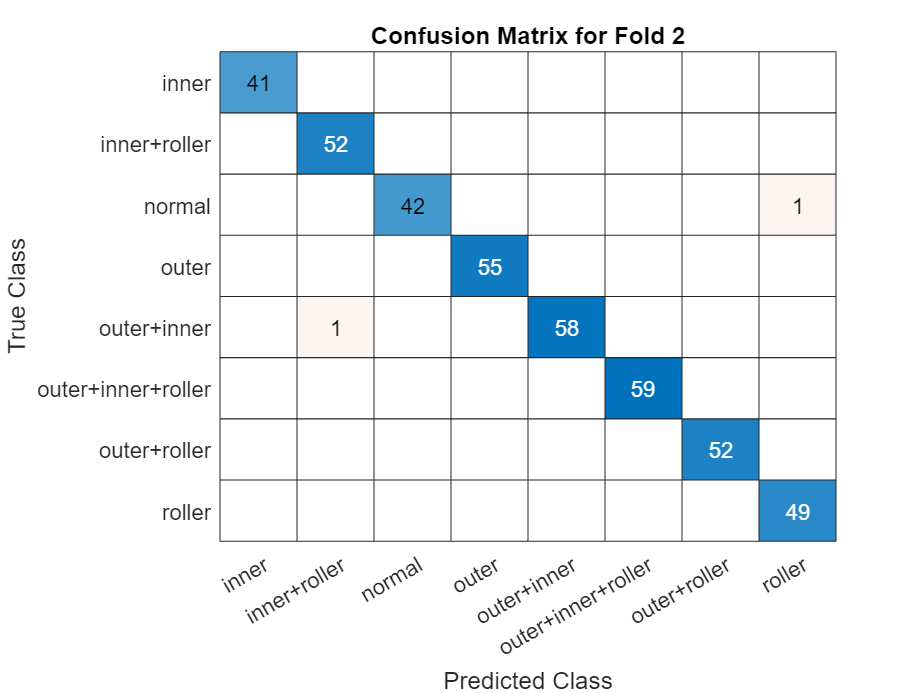

Fold 3


    62     0     0     0     0     0     0     0
     0    43     0     0     0     0     0     0
     0     0    53     0     0     0     0     0
     0     0     0    53     0     0     0     0
     0     0     0     0    53     1     0     0
     0     0     0     0     0    50     0     0
     0     0     0     0     0     0    54     0
     0     0     0     0     0     0     0    41



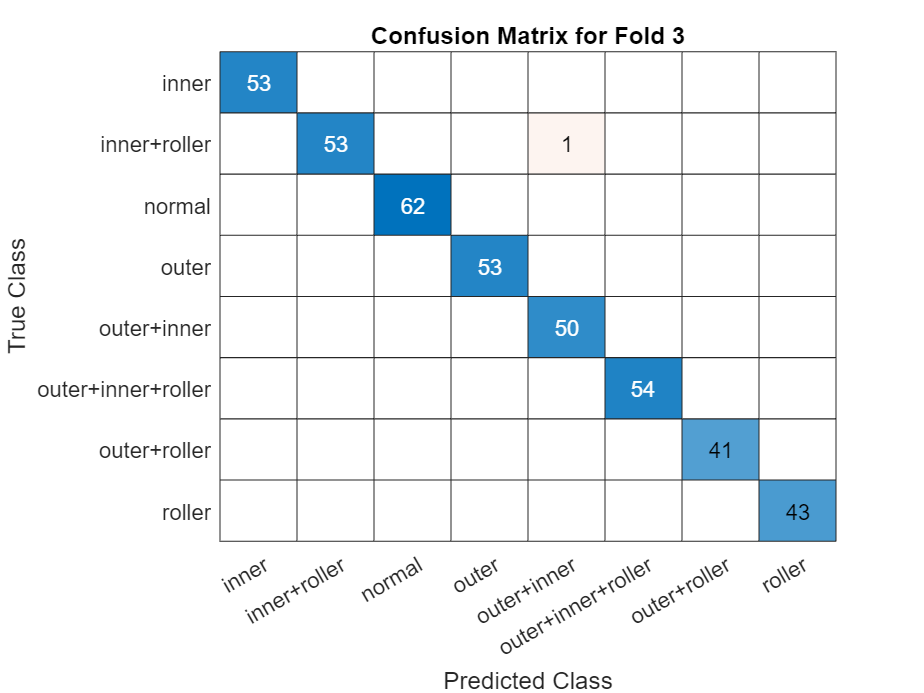

Fold 4


    48     0     0     0     0     0     0     0
     0    62     0     0     0     0     0     0
     0     0    50     0     0     0     0     1
     0     0     0    47     0     0     0     0
     0     0     0     0    50     3     0     0
     0     0     0     0     3    53     0     0
     0     0     0     0     0     0    39     0
     0     0     0     0     0     0     0    54



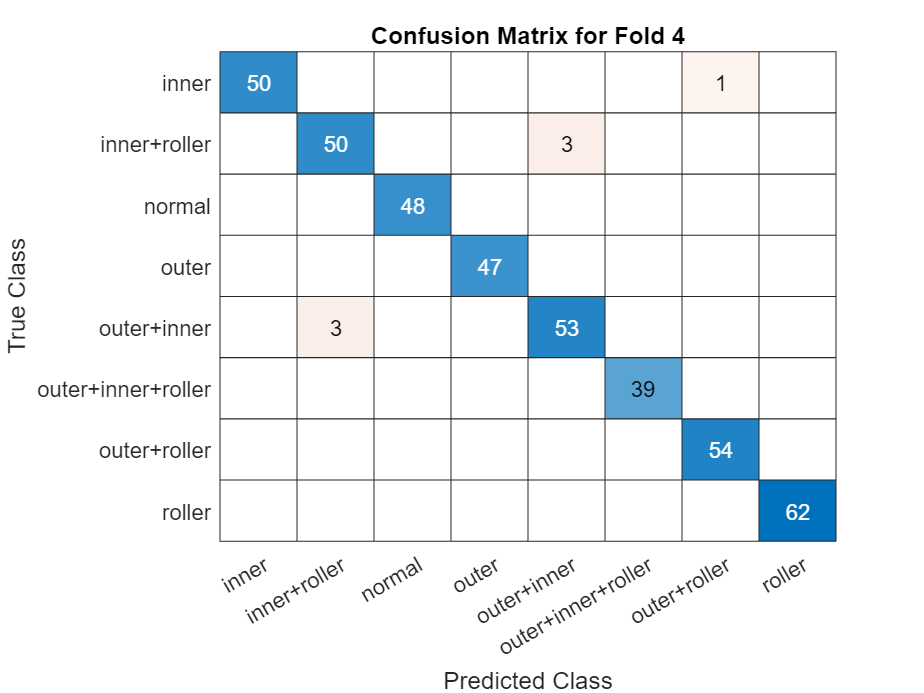

Fold 5


    53     0     0     0     0     0     0     0
     0    49     0     0     0     0     0     0
     0     0    51     0     0     0     0     0
     0     0     0    50     0     0     0     0
     0     0     0     0    58     0     0     0
     0     0     0     0     1    46     0     0
     0     0     0     0     0     0    47     0
     0     0     0     0     0     0     0    54



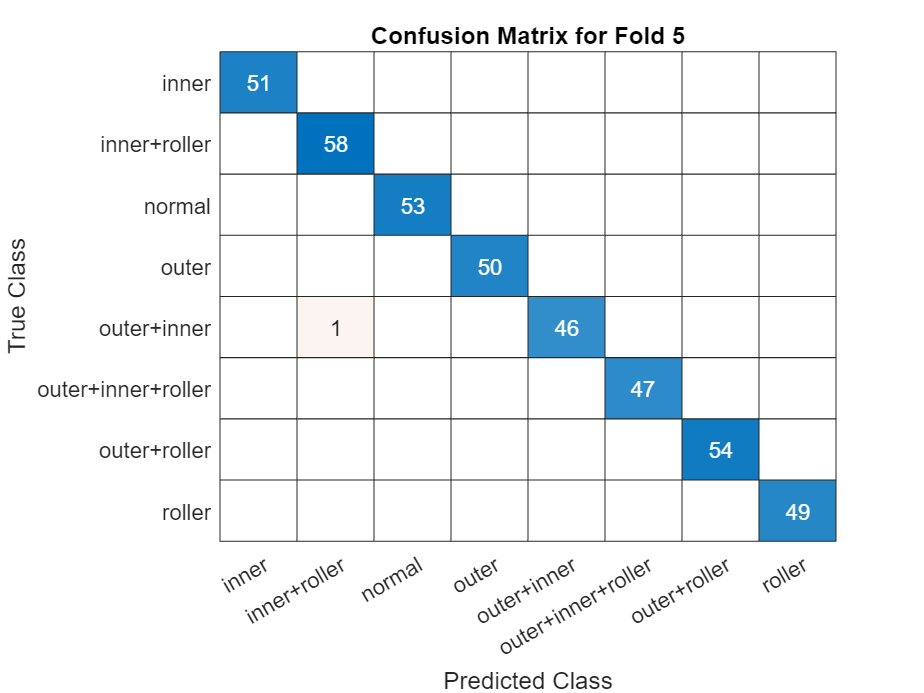


for i = 1:k
    disp(['Fold ', num2str(i)]);
    disp(conf_matrices_som{i});
    
    % Create confusion matrix plot
    figure;
    confusionchart(conf_matrices_som{i}, label_names);
    title(['Confusion Matrix for Fold ', num2str(i)]);
end